## 1.绘制频谱结果

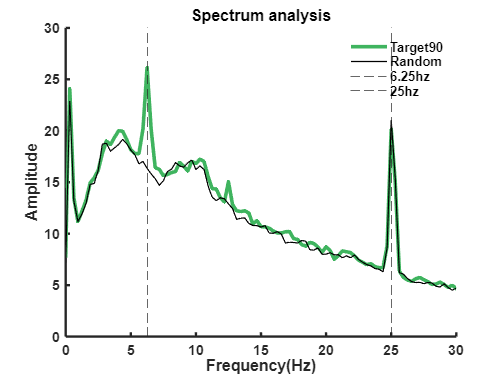

Fs = 500;                   
N = 1600;                   
f = Fs * (0:N/2) / N; 
figure;
coil = 63;
blocklaberl = {'Target10','Target30','Target50','Target70','Target90','Target110','Target130','Target150','Target170','Blank','Random'};
for block = [5,11]
    meanfft = squeeze(mean(fftplot{block}{1}(:,coil,:),1));
    if block == 10              % blank
        plot(f, meanfft, 'LineWidth', 1.0,'DisplayName',blocklaberl{block},'Color',[0.8,0.8,0.8]);
    elseif block == 11         %random
        plot(f, meanfft, 'LineWidth', 1.0,'DisplayName',blocklaberl{block},'Color',[0,0,0]);
    else
        plot(f, meanfft, 'LineWidth', 3.0,'DisplayName',blocklaberl{block},'Color',[63,181,95]/256);
        % plot(f, meanfft, 'LineWidth', 3.0,'DisplayName',blocklaberl{block},'Color',[233,171,101]/256);
        % plot(f, meanfft, 'LineWidth', 3.0,'DisplayName',blocklaberl{block},'Color',[70,185,101]/256);
        % plot(f, meanfft, 'LineWidth', 3.0,'DisplayName',blocklaberl{block},'Color',[113,154,172]/256);
    end
    hold on
end
hold off
box off;
title('Spectrum analysis',"FontSize",14,'FontWeight',"bold");
xlabel('Frequency(Hz)');
ylabel('Amplitude');
% ylabel('Phase');
xline(6.25,'LineStyle',"--",'DisplayName','6.25hz');
xline(25,'LineStyle',"--",'DisplayName','25hz');
xlim([0 30]);               % 聚焦0-30Hz范围（包含6.25Hz和25Hz）
legend('Box',"off");
% set(gca, 'FontSize', 12,'FontWeight','bold'); 
ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

## 2.显著性分析

figure;
fft_p_predata = squeeze(SSVEP_data{5}(:,63,:));
data1 = fft_p_predata(:,f==6.25);
data2 = mean(fft_p_predata(:,(f>=5.25&f<=7.25)),2);
data3 = fft_p_predata(:,f==25);
data4 = mean(fft_p_predata(:,(f>=24&f<=26)),2);

% 组织数据为两组
data = [data1, data2, data3, data4];
categories = {'6.25hz', '6.25Noise', '25hz', '25Noise'};

figure;
violins = violinplot(data, categories, ...
    'ViolinColor', [0.2 0.6 0.8; 0.8 0.4 0.1;0.2 0.6 0.8;0.2 0.6 0.8], ... % 蓝色和橙色
    'ShowMean', true, ... 
    'EdgeColor', [0.3 0.3 0.3], ... % 边缘颜色
    'BoxColor', [0.3 0.3 0.3]); 

% 美化图形
xlabel('Distribution Type');
ylabel('Value');
title('Violin Plot: Normal vs Uniform');
set(gca, 'FontSize', 12);
grid on;

figure;
boxplot(data);

## 3.d-prime

Fs = 500;                   
N = 1600;                   
f = Fs * (0:N/2) / N;  
coilnum = 24;
load('D:\\Ensemble coding\\data\\SNR.mat','coilSNR');
[~,coilidx] = sort(coilSNR,'descend');
coilselect = coilidx(1:coilnum);

d_primedatatarget = squeeze(DatafftAmplitude{1,5}(:,coilselect,:));
d_primedatarandom = squeeze(DatafftAmplitude{1,1}(:,coilselect,:));

d_primeresult = zeros(1,coilnum);
for coil = 1:coilnum
    d_primesignal = squeeze(d_primedatatarget(:,coil,f==6.25));
    d_primenoise = squeeze(d_primedatarandom(:,coil,f==6.25));
    d_primeresult(coil) = compute_dprime(d_primesignal, d_primenoise);
    
end

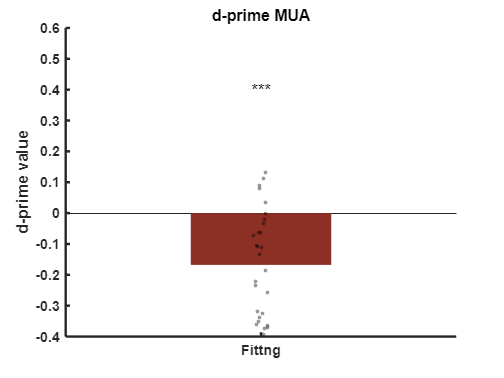

figure;
d_primeresult_EC = d_primeresult;
d_primeresult_EC0 = d_primeresult;
b = bar(mean(d_primeresult_EC'), ...
    'FaceColor', 'flat', 'BarWidth', 0.9, 'LineWidth', 2,'EdgeColor','none');
b.CData(1,:) = [141,47,37]/256;  % 第一个bar颜色（绿色）
% b.CData(2,:) = [131,145,111]/256;  % 第二个bar颜色（红色）

% 添加数据点散点（带jitter）
hold on;
jitter = @(x, scale) x + scale * (rand(size(x)) - 0.5);
x1 = jitter(ones(size(d_primeresult_EC)), 0.1);
%x2 = jitter(ones(size(d_primeresult_EC0))+1, 0.1);
scatter(x1(2:end), d_primeresult_EC(2:end), 10, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
%scatter(x2, d_primeresult_EC0, 10, 'k', 'filled', 'MarkerFaceAlpha', 0.4);

% 连接相同电极的数据点
% for i = 1:length(d_primeresult_EC)
%     plot([x1(i), x2(i)], [d_primeresult_EC(i), d_primeresult_EC0(i)], ...
%         'Color', [0.5 0.5 0.5 0.3], 'LineWidth', 0.5);
% end

% 添加显著性标记
[h, p] = ttest(d_primeresult_EC, 0);
y_max = max([d_primeresult_EC; d_primeresult_EC0]);
y_line = y_max + 0.1 * range([d_primeresult_EC; d_primeresult_EC0]);

if p < 0.001
    sig_text = '***';
elseif p < 0.01
    sig_text = '**';
elseif p < 0.05
    sig_text = '*';
else
    sig_text = 'n.s.';
end

if p < 0.05
    plot([1, 2], [1.3, 1.3], '-k', 'LineWidth', 2.0);
    text(1.5, 1.35, ...
        sig_text, 'FontSize', 14, 'HorizontalAlignment', 'center');
end
text(1, 0.4, ...
        sig_text, 'FontSize', 14, 'HorizontalAlignment', 'center');
%text(2, 0.3, ...
        % sig_text, 'FontSize', 14, 'HorizontalAlignment', 'center');
% 美化图形
title('d-prime MUA', 'FontSize', 15, 'FontWeight', 'bold');
xticklabels({'Fittng'});
ylabel('d-prime value');
box off;

% 设置坐标轴样式
ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;
ax.XAxis.FontWeight = 'bold';

% 添加图例
% legend([b, scatter(nan, nan, 'k', 'filled')], {'Mean', 'Individual electrodes'}, ...
%     'Location', 'best', 'Box', 'off');

% 调整坐标轴范围
% ylim([min([d_primeresult_EC; d_primeresult_EC0]) - 0.1 * range([d_primeresult_EC; d_primeresult_EC0]), ...
%       max([d_primeresult_EC; d_primeresult_EC0]) + 0.2 * range([d_primeresult_EC; d_primeresult_EC0])]);
ylim([-0.4,0.6]);

## 4.不同朝向的差异

fre1_tuning = zeros(9,96);
fre2_tuning = zeros(9,96);
for ori =1 :9
    for coil = 1:96
        fre1_tuning(ori,coil) = squeeze(mean(fftplot{ori}(:,coil,f==6.25),1));
        fre2_tuning(ori,coil) = squeeze(mean(fftplot{ori}(:,coil,f==25),1));
    end
end
figure;
load('/home/dclab2/Ensemble coding/data/chanmap.mat')
for coil = 1:96
    n = find(ChanMap==coil);
    subplot(10,10,n);
    plot(log10(fre1_tuning(:,coil)));
    hold on
    plot(log10(fre2_tuning(:,coil)));
    hold off
end





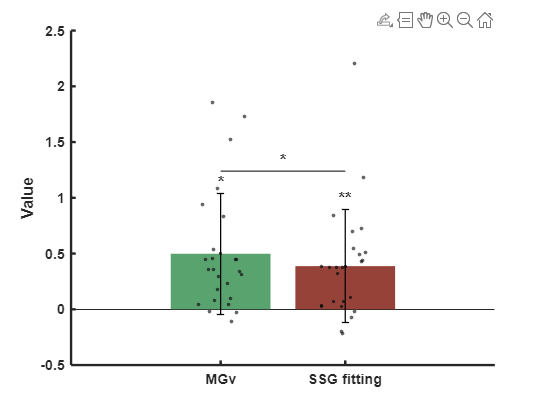

% 示例数据
data = [MGv;  % 序列2
        SSG_fitting]; % 序列3
groups = {'MGv', 'SSG fitting'}; % 组别名称

% 计算均值和标准差
mean_data = mean(data, 2);
std_data = std(data, 0, 2);

% 创建figure
figure('Position', [100, 100, 800, 600]);
hold on;

% 绘制柱状图
b = bar(mean_data);
set(b, 'FaceColor', 'flat','EdgeColor','none');
% b.CData = [98 141 161; 214 127 32; 89 164 110]/255;
b.CData = [89 164 110;150 66 57]/255; % 自定义颜色

% 绘制误差条（标准差）
errorbar(1:2, mean_data, std_data, 'k.', 'LineWidth', 1.0);

% 绘制原始数据点
for i = 1:2
    scatter(ones(size(data, 2),1)*i - 0.2 + 0.4*rand(size(data, 2),1), ...
            data(i,:), 10, 'k', 'filled', 'MarkerEdgeColor', 'w','MarkerFaceAlpha',0.6,'MarkerEdgeAlpha',0.1);
end

% 假设的显著性检验结果（实际中你需要用统计检验计算）
p_values = [0.02, 0.001, 0.03;  % 与0比较的p值
            0.04, 0.01, 0.45];   % 组间比较的p值

% 标注与0的显著性
for i = 1:2
    if p_values(1,i) < 0.001
        text(i, mean_data(i)+std_data(i)+0.1, '***', 'HorizontalAlignment', 'center','FontSize',14,'FontWeight','bold');
    elseif p_values(1,i) < 0.01
        text(i, mean_data(i)+std_data(i)+0.1, '**', 'HorizontalAlignment', 'center','FontSize',14,'FontWeight','bold');
    elseif p_values(1,i) < 0.05
        text(i, mean_data(i)+std_data(i)+0.1, '*', 'HorizontalAlignment', 'center','FontSize',14,'FontWeight','bold');
    end
end

% 标注组间显著性
% 组1 vs 组2
if p_values(2,1) < 0.05
    plot([1, 2], [max(mean_data(1:2))+max(std_data(1:2))+0.2, max(mean_data(1:2))+max(std_data(1:2))+0.2], 'k');
    text(1.5, max(mean_data(1:2))+max(std_data(1:2))+0.3, '*', 'HorizontalAlignment', 'center','FontSize',14,'FontWeight','bold');
end
% 组2 vs 组3
% if p_values(2,2) < 0.05
%     plot([2, 3], [max(mean_data(2:3))+max(std_data(2:3))+0.4, max(mean_data(2:3))+max(std_data(2:3))+0.4], 'k');
%     text(2.5, max(mean_data(2:3))+max(std_data(2:3))+0.5, '*', 'HorizontalAlignment', 'center','FontSize',14,'FontWeight','bold');
% end

% 美化图形
set(gca, 'XTick', 1:2, 'XTickLabel', groups, 'FontSize', 12);
ylabel('Value', 'FontSize', 14);
% title('D-prime', 'FontSize', 16);

box off;

% 添加图例
%legend('Mean', 'Standard Deviation', 'Data Points', 'Location', 'northwest');

hold off;
ax = gca;
ax.LineWidth = 2;
ax.FontSize = 12;
ax.FontWeight = 'bold';
ax.XAxis.FontSize = 12;
ax.YAxis.FontSize = 12;

ax.XAxis.FontWeight = 'bold';